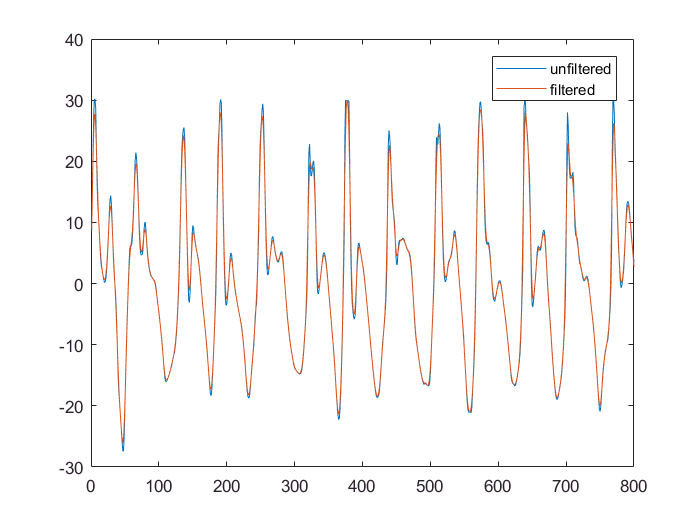

load 'crunchedData.mat'

% Filter the data
anyafilt = avgfilter(anya,true);

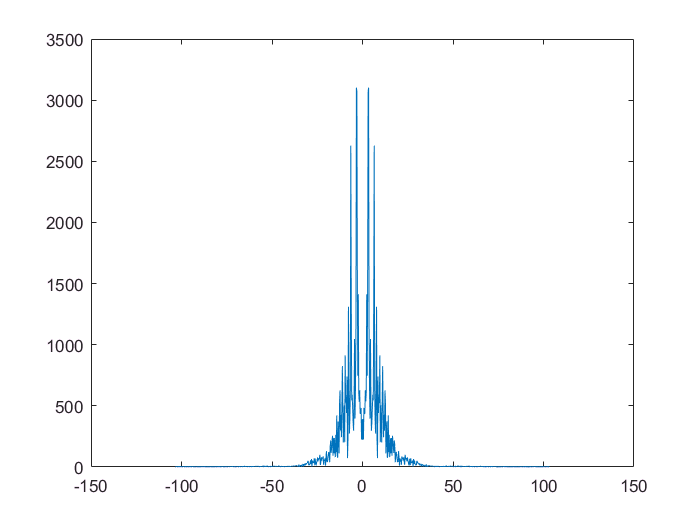

% Find the period for each dataset
[anyap, anyamax] = findperiod(anyafilt,1);

% Chop data up into each period and put in matrix
% (each row is a stride)
anyastride = chop(anyafilt, anyap);
size(anyastride);

% Find average stride
anyamean = mean(anyastride);

[anyamtx,anyam] = doitall(anya,0);
[chasmtx,chasm] = doitall(chas,0);
[colimtx,colim] = doitall(coli,0);
[cusamtx,cusam] = doitall(cusa,0);
[diegmtx,diegm] = doitall(dieg,0);
[jamemtx,jamem] = doitall(jame,0);
[julimtx,julim] = doitall(juli,0);
[kawimtx,kawim] = doitall(kawi,0);
[natemtx,natem] = doitall(nate,0);
[rickmtx,rickm] = doitall(rick,0);
maxs = [anyam,chasm,colim,cusam,diegm,jamem,julim,kawim,natem,rickm];
meanall = mean(maxs);
stdall = std(maxs);
noahs = [269,9,217,317,280,259,257,183,217,153,198];
mean(noahs)

ans = 214.4545

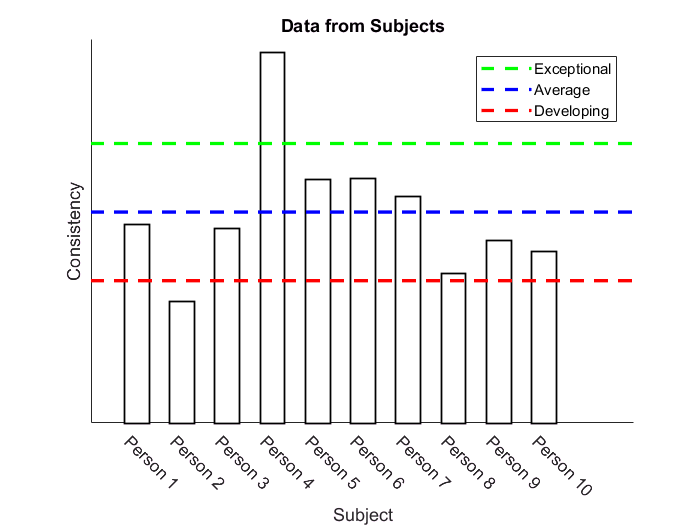

% Plotting the data
subjects = {'Person 1','Person 2','Person 3','Person 4','Person 5','Person 6','Person 7','Person 8','Person 9','Person 10'};

figure
clf
hold on;
bar_graph = bar(maxs,0.55,'FaceColor',[1 1 1],'EdgeColor',[0 0 0], 'LineWidth',1,'HandleVisibility','off');
% avg_bar = bar(11,maxs(11),0.55,'FaceColor',[0 0 0.7],'EdgeColor',[0 0 0.7]);
% set(gca,'xticklabel',subjects)
xticks([1,2,3,4,5,6,7,8,9,10])
xticklabels(subjects)
xtickangle(-45)
aline = refline([0,(meanall+stdall)]);
aline.Color = 'green';set(aline,'LineStyle','--','LineWidth',2);
hline = refline([0,meanall]);
hline.Color = 'b';set(hline,'LineStyle','--','LineWidth',2);
uline = refline([0,(meanall-stdall)]);
uline.Color = 'r';set(uline,'LineStyle','--','LineWidth',2);
ylabel('Consistency')
xlabel('Subject')
title('Data from Subjects')
legend('Exceptional','Average','Developing')
yticks([])
hold off;

function filterdata = avgfilter(data,p)
%     Filters the data using an average of 5 datapoints
    h = [1/5,1/5,1/5,1/5,1/5];
    filterdata = conv(data,h, 'same');
    if p == 1
        figure
        clf
        plot(data)
        hold on
        plot(filterdata)
        legend('unfiltered','filtered')
    end
end
function [period,M] = findperiod(data,p)
    fftdata = fftshift(abs(fft(data))); %no fftshift?
    [M,I] = max(abs(fftdata));
    N = length(data);
    Fs = 207;
    freq = linspace(-Fs/2, Fs/2 - Fs/N, N) + mod(N, 2)/(2*N);
    period = 1/freq(I);
    if p == 1
        figure
        clf
        plot(freq,fftdata)
    end
end
function out = chop(data,period)
    %Period should not be in Hz
    Fs = 207;
    chopsize = round(abs(period)*Fs);
    rem = mod(length(data),chopsize);
    gooddata = data(1:end-rem); %might not line up, off by one?
    out = zeros(length(gooddata)/chopsize,chopsize);
    for n = 1:length(gooddata)/chopsize
        out(n,:) = gooddata((n-1)*chopsize+1:n*chopsize);
    end
end
function [out,M] = doitall(data,p)
    filt = avgfilter(data,p);
    [per,M] = findperiod(filt,p);
    out = mean(chop(filt,per));
end